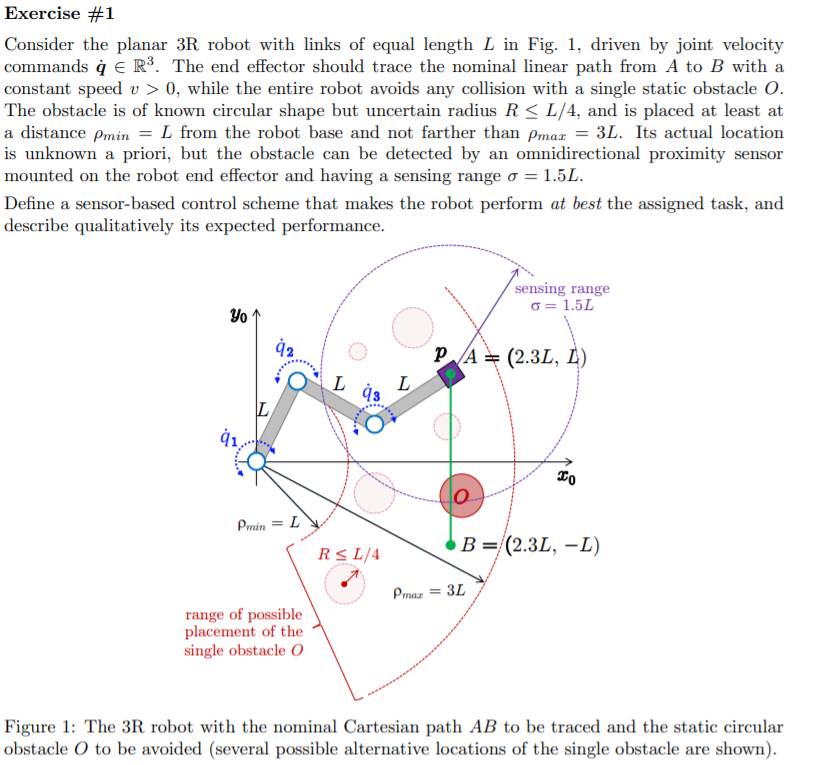

%done by hand


## 2

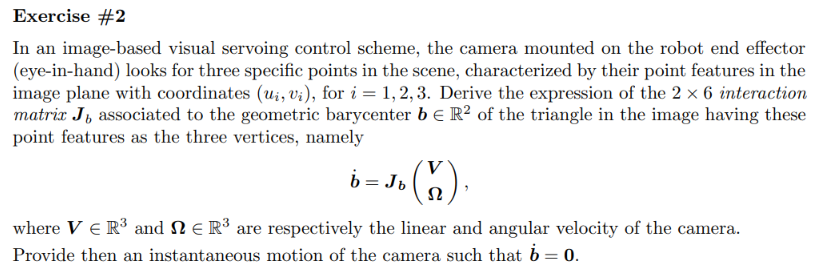

clc;clear;
[J_camera,velocities,V,OMEGA]=gen_interaction_matrix(2)

J_camera = 1×1 cell array
    {2×6 sym}


J_camera = 1×2 cell array
    {2×6 sym}    {2×6 sym}


J_camera = 1×2 cell array
    {2×6 sym}    {2×6 sym}


velocities = 1×2 cell array
    {1×1 struct}    {1×1 struct}


$$V = \left(\begin{array}{c} V_{1}\\ V_{2}\\ V_{3} \end{array}\right)$$

$$OMEGA = \left(\begin{array}{c} \Omega_{1}\\ \Omega_{2}\\ \Omega_{3} \end{array}\right)$$

J_b=(J_camera{1}+J_camera{2})/2

$$J\_b = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{1} & 0 & \frac{u_{1}}{2\,Z_{1}}+\frac{u_{2}}{2\,Z_{2}} & \sigma_{3}+\sigma_{2} & -\lambda -\frac{{u_{1}}^{2}}{2\,\lambda }-\frac{{u_{2}}^{2}}{2\,\lambda } & \frac{v_{1}}{2}+\frac{v_{2}}{2}\\ 0 & \sigma_{1} & \frac{v_{1}}{2\,Z_{1}}+\frac{v_{2}}{2\,Z_{2}} & \lambda +\frac{{v_{1}}^{2}}{2\,\lambda }+\frac{{v_{2}}^{2}}{2\,\lambda } & -\sigma_{3}-\sigma_{2} & -\frac{u_{1}}{2}-\frac{u_{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\lambda }{2\,Z_{1}}-\frac{\lambda }{2\,Z_{2}}\\ \sigma_{2}=\frac{u_{2}\,v_{2}}{2\,\lambda }\\ \sigma_{3}=\frac{u_{1}\,v_{1}}{2\,\lambda } \end{array}$$

% J_b=(J_camera{1}+J_camera{2}+J_camera{3})/3
OMEGA=[0,0,0]' 

OMEGA =      0
     0
     0


vel_=J_b*[V;OMEGA]

$$vel\_ = \left(\begin{array}{c} V_{3}\,\left(\frac{u_{1}}{2\,Z_{1}}+\frac{u_{2}}{2\,Z_{2}}\right)-V_{1}\,\left(\frac{\lambda }{2\,Z_{1}}+\frac{\lambda }{2\,Z_{2}}\right)\\ V_{3}\,\left(\frac{v_{1}}{2\,Z_{1}}+\frac{v_{2}}{2\,Z_{2}}\right)-V_{2}\,\left(\frac{\lambda }{2\,Z_{1}}+\frac{\lambda }{2\,Z_{2}}\right) \end{array}\right)$$

resn=(simplify(null(J_b))) %one ofthis solutions works well also

$$resn = \begin{array}{l} \left(\begin{array}{cccc} \frac{Z_{1}\,u_{2}+Z_{2}\,u_{1}}{\lambda \,\left(Z_{1}+Z_{2}\right)} & \sigma_{1} & -\frac{Z_{1}\,Z_{2}\,\left(2\,\lambda^{2}+{u_{1}}^{2}+{u_{2}}^{2}\right)}{\sigma_{2}} & \frac{Z_{1}\,Z_{2}\,\left(v_{1}+v_{2}\right)}{\lambda \,\left(Z_{1}+Z_{2}\right)}\\ \frac{Z_{1}\,v_{2}+Z_{2}\,v_{1}}{\lambda \,\left(Z_{1}+Z_{2}\right)} & \frac{Z_{1}\,Z_{2}\,\left(2\,\lambda^{2}+{v_{1}}^{2}+{v_{2}}^{2}\right)}{\sigma_{2}} & -\sigma_{1} & -\frac{Z_{1}\,Z_{2}\,\left(u_{1}+u_{2}\right)}{\lambda \,\left(Z_{1}+Z_{2}\right)}\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{Z_{1}\,Z_{2}\,\left(u_{1}\,v_{1}+u_{2}\,v_{2}\right)}{\sigma_{2}}\\ \sigma_{2}=\lambda^{2}\,\left(Z_{1}+Z_{2}\right) \end{array}$$

res1=simplify(J_b*resn(:,1))

$$res1 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

% J_b(1,1)
% J_b(1,3)
% simplify(J_b(1,3)/J_b(1,1))

% res=solve([vel_==0;V~=0],[V])

% % res.Omega_1
% res.V_1
% res.V_2
% res.V_3

## 3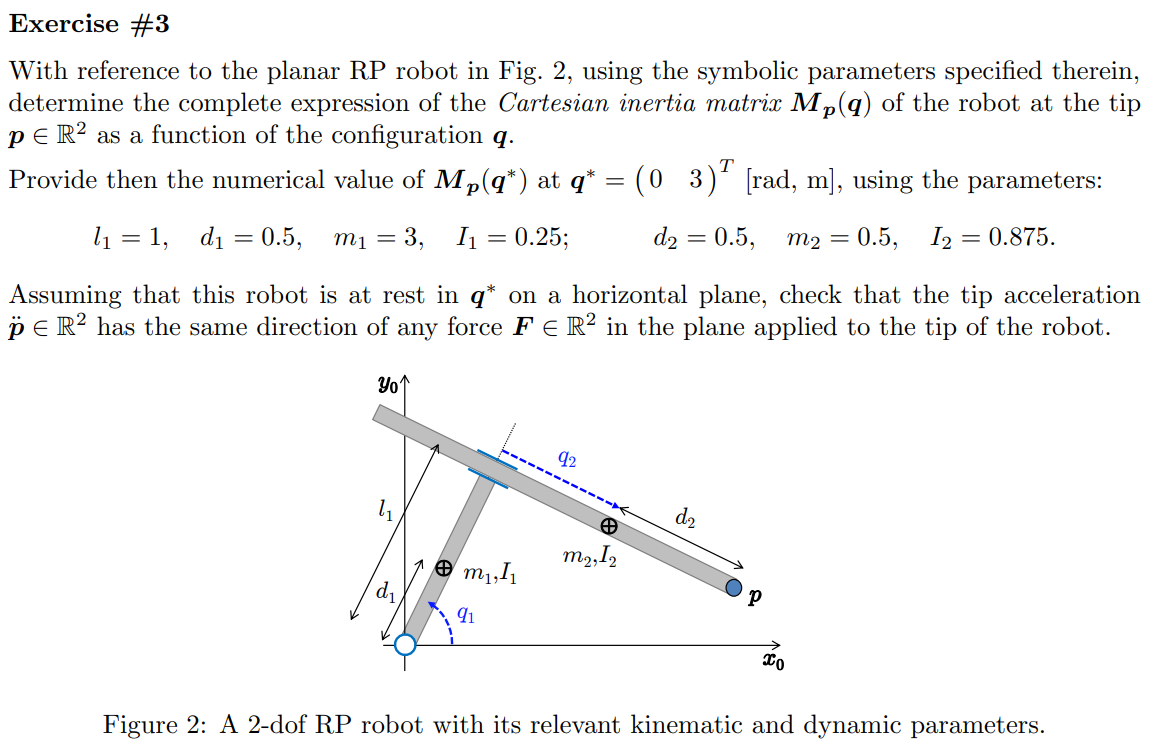

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [1,0];
% R2Robot=['rp';'xy';sigmaD]
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.angle_(2)=sym(pi);
% z.opt_expr={[q(2)],[-q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

% 
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z)
% 

% Pc
% 
% M
% Trans.PTotal

% J=jacobian(Pc(:,2),z.q)

% J_inv=simplify(pinv(J))
% Mp=(J_inv'*M*J_inv)

% 

% % [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

% % cac
% % S

% % [Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[],2)

% q_=[0,3]'
% l_=[1,z.l(2)]'
% dc_=[0.5,0.5]'
% m_=[3,0.5]'
% I_=[0.25,0.875]'
% to_replace=[z.q;z.l;z.dc;z.m;z.I]
% to_replace_=[q_;l_;dc_;m_;I_]

% Mp_=vpa(subs(Mp,to_replace,to_replace_))

% F=sym('F_',[3,1],'real')
% p_ddot_=pinv(Mp_)*F

## 4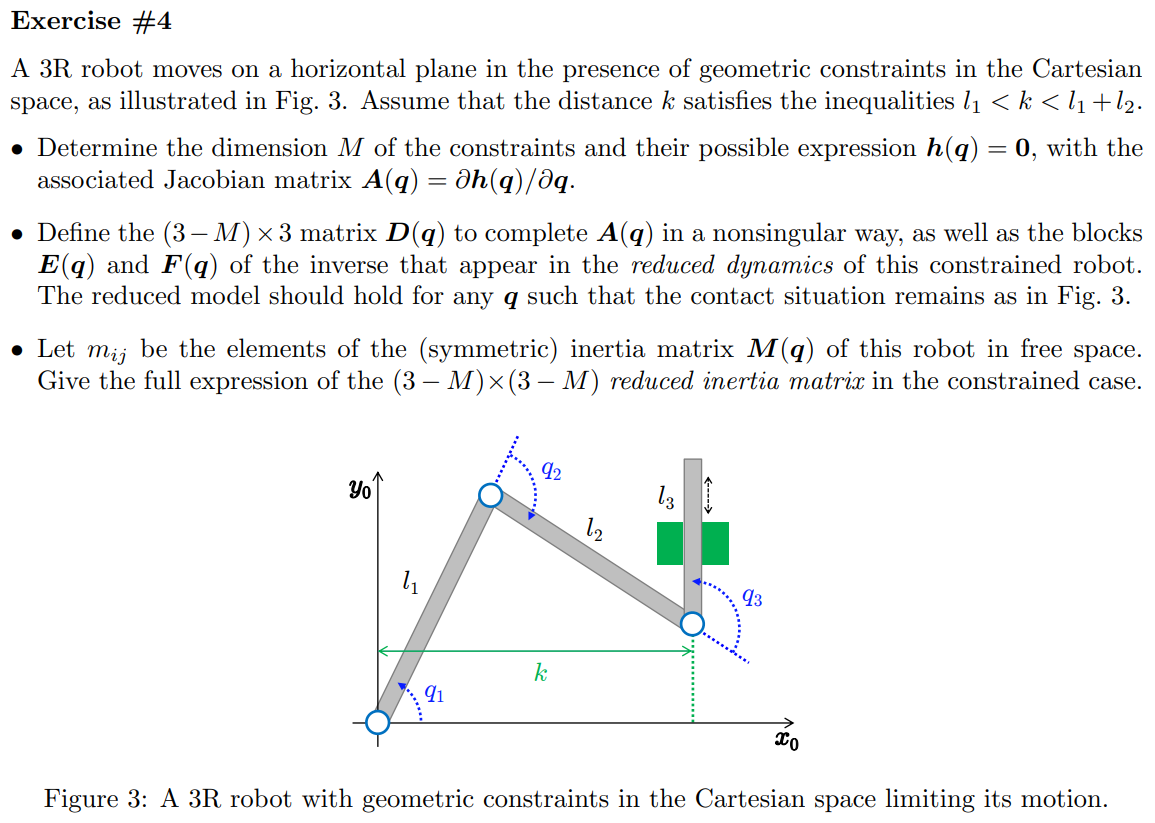

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [1,1,1];
% R2Robot=['rrr';'xxx';sigmaD]
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.angle_(2)=sym(pi);
% % z.opt_expr={[q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

% 
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z)
% 

% Pc
% 
% M
% Trans.PTotali(:,2)
% 

% k=sym('k','real')
% A_sym=sym('A',[n,n],'real')
% h=[sum(z.q)-pi-2;Trans.PTotali(1,2)-k]
% D_int=Trans.PTotali(2,2)
% A=jacobian(h,z.q)
% D=jacobian(D_int,z.q)

% [dyn_red]=dynamics_reduction(h,D,z)

## reduced M

% M_sym=sym('M_',[n,n],'real')
% to_collect=[sin(z.q(1)+z.q(2)),sin(z.q(1))]
% 
% 
% (collect(simplify(M_sym*dyn_red.F),to_collect))%,to_collect2)
% M_red=simplify(dyn_red.F'*M_sym*dyn_red.F)

% % to_collect2=[1/sin(z.q(2)),sin(z.q(1)+z.q(2))^2,sin(z.q(1))^2]
% to_collect2=[sin(z.q(1))^2,sin(z.q(1)+z.q(2))^2,(l(1)*l(2)/sin(z.q(2)))^2]
% (collect(simplify(dyn_red.M_red),to_collect2))

## 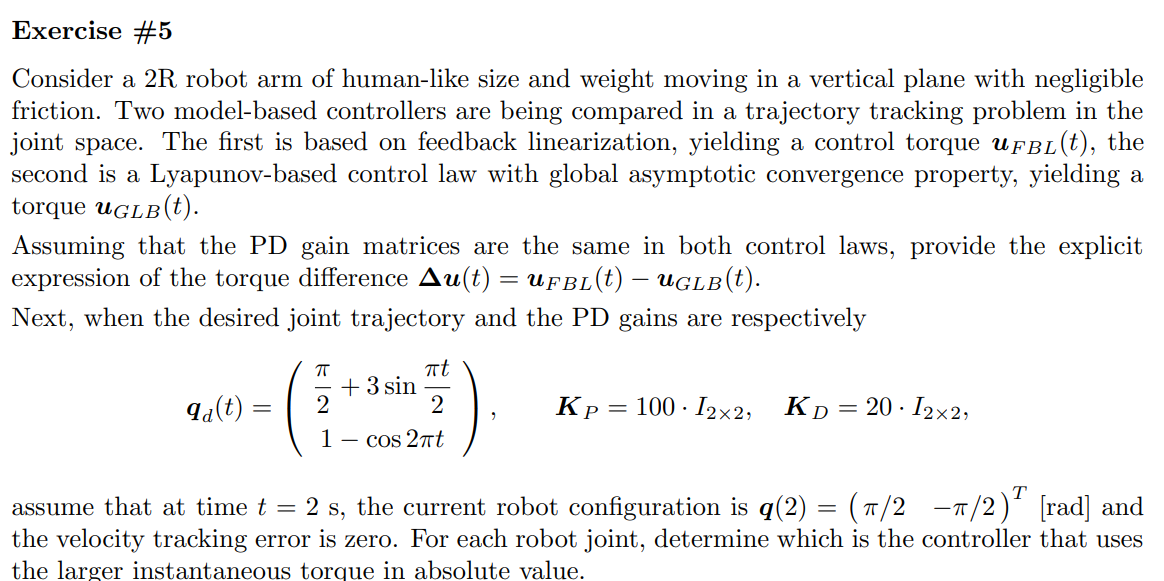

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [1,1];
% R2Robot=['rr';'xx';sigmaD]
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.angle_(2)=sym(pi);
% % z.opt_expr={[q(2)],[-q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

% % 
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z)
% % 

% Pc
% % 
% M
% % Trans.PTotal

% % J=jacobian(Pc(:,2),z.q)

% % J_inv=simplify(pinv(J))
% % Mp=(J_inv'*M*J_inv)

% % 

% [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

% cac
% S

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor);

% % [Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[],2)
% [All, dynamicParameters, aM] = getDynamicParameters2([M,S,g_q],z.q,[z.q_dot],2);

% Msubs=All(:,1:n)
% Ssubs=All(:,n+1:2*n)
% Gsubs=All(:,2*n+1)
% aM

% t=sym('t','real')
% q_d         =[pi/2+3*sin(pi*t/2),1-cos(2*pi*t)]'
% q_d_dot     =simplify(diff(q_d))

% t_=2
% q_      =[pi/2,-pi/2]'
% 
% % q_d_    =[pi/2+3*sin(pi*t_/2),1-cos(2*pi*t_)]'
% 
% % l_=[1,z.l(2)]'
% % dc_=[0.5,0.5]'
% % m_=[3,0.5]'
% % I_=[0.25,0.875]'
% to_replace=[z.q;t]
% to_replace_=[q_;t_]

% q_d_dot_=vpa(subs(q_d_dot,to_replace,to_replace_))
% q_dot_ =q_d_dot_
% % q_d_dot_  =[0,0]'
% e_=q_d_-q_
% 
% e_dot_=q_d_dot_-q_dot_
% 
% to_replace=[z.q;z.q_dot;t]
% to_replace_=[q_;q_dot_;t_]

% M_=vpa(subs(Msubs,to_replace,to_replace_))
% S_=vpa(subs(Ssubs,to_replace,to_replace_))

% K_P=diag([20,20])
% K_D=diag([100,100])
% K_res_=round((K_D*e_dot_+K_P*e_),5)
% delta_u_=vpa((M_-eye(size(M)))*K_res_)